% Posición inicial (x, y, theta) en metros y radianes
pose = [-1; -5; 0];  

% Matriz de comandos: [v, omega, dt] para cada paso (12 pasos)
commands = [...
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0;
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0;
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0;
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0;
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0;
    1.0, 0.0, 1.0;
    0.0, pi/3, 1.0 ];

% Prealocar memoria para guardar las poses
poses = zeros(3, length(commands)+1);
poses(:,1) = pose; % Guardar la pose inicial

% Iterar sobre cada paso
for k = 1:length(commands)
    v = commands(k, 1);
    omega = commands(k, 2);
    dt = commands(k, 3);

    delta_d = v * dt;
    delta_theta = omega * dt;

    % Actualizar pose usando el modelo de movimiento
    pose(1) = pose(1) + delta_d * cos(pose(3));
    pose(2) = pose(2) + delta_d * sin(pose(3));
    pose(3) = pose(3) + delta_theta;

    % Guardar la nueva pose
    poses(:, k+1) = pose;
end

% Mostrar las poses
disp('Poses en cada paso:')

Poses en cada paso:


disp(poses')

   -1.0000   -5.0000         0
         0   -5.0000         0
         0   -5.0000    1.0472
    0.5000   -4.1340    1.0472
    0.5000   -4.1340    2.0944
    0.0000   -3.2679    2.0944
    0.0000   -3.2679    3.1416
   -1.0000   -3.2679    3.1416
   -1.0000   -3.2679    4.1888
   -1.5000   -4.1340    4.1888
   -1.5000   -4.1340    5.2360
   -1.0000   -5.0000    5.2360
   -1.0000   -5.0000    6.2832



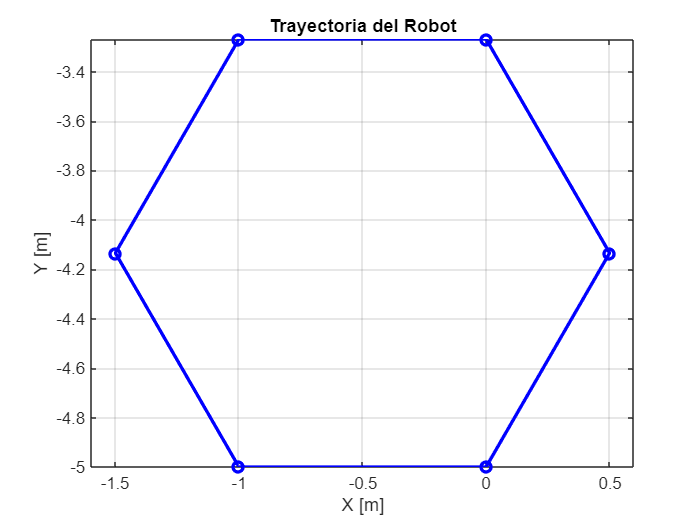


% Graficar trayectoria
figure;
plot(poses(1,:), poses(2,:), 'b-o', 'LineWidth', 2);
xlabel('X [m]');
ylabel('Y [m]');
title('Trayectoria del Robot');
axis equal;
grid on;



fprintf('Pose final del robot:\n');

Pose final del robot:


fprintf('x = %.2f m\n', pose(1));

x = -1.00 m


fprintf('y = %.2f m\n', pose(2));

y = -5.00 m


fprintf('theta = %.2f rad (%.2f grados)\n', pose(3), rad2deg(pose(3)));

theta = 6.28 rad (360.00 grados)






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parámetros del robot
r = 0.1;   % Radio de rueda [m]
l = 0.4;   % Distancia entre ruedas [m]

% Pose inicial
pose = [0; 0; 0];   % [x, y, theta] en [m, m, rad]

% Velocidades angulares (extraídas de las imágenes)
wheel_speeds = [
    4.582, 1.701;
    4.773, 2.353;
    5.291, 3.676;
    5.960, 4.856;
    6.490, 5.618;
    -1.168, 13.735;
    -1.364, 13.472;
    5.960, 4.856;
    5.291, 3.676;
    4.773, 2.353;
    4.582, 1.701;
    4.773, 2.353;
    5.291, 3.676;
    5.960, 4.856;
    6.490, 5.618;
    6.686, 5.881;
    6.490, 5.618;
    5.960, 4.856;
    5.291, 3.676;
    4.773, 2.353;
    4.582, 1.701
];

dt = 1.0;  % Tiempo por paso (s)
n = size(wheel_speeds, 1);

% Inicialización de matrices
poses = zeros(3, n+1);
V_list = zeros(n, 1);
W_list = zeros(n, 1);

poses(:, 1) = pose;

% Iteración
for k = 1:n
    wR = wheel_speeds(k, 1);
    wL = wheel_speeds(k, 2);

    % Cálculo de velocidades
    V = r * (wR + wL) / 2;
    W = r * (wR - wL) / l;

    V_list(k) = V;
    W_list(k) = W;

    % Pose anterior
    x = pose(1);
    y = pose(2);
    theta = pose(3);

    % Nueva pose
    x = x + V * dt * cos(theta);
    y = y + V * dt * sin(theta);
    theta = theta + W * dt;

    % Actualizar
    pose = [x; y; theta];
    poses(:, k+1) = pose;
end

% Mostrar resultados
fprintf('Pose final:\n');

Pose final:


fprintf('x = %.3f m\ny = %.3f m\ntheta = %.3f rad (%.1f°)\n', ...
    pose(1), pose(2), pose(3), rad2deg(pose(3)));

x = -0.226 m
y = -0.408 m
theta = 0.720 rad (41.3°)



% Tabla de resultados
T = table((1:n)', V_list, W_list, ...
    'VariableNames', {'Paso', 'Vel_Lineal_m_s', 'Vel_Angular_rad_s'});
disp(T)

    Paso    Vel_Lineal_m_s    Vel_Angular_rad_s
    ____    ______________    _________________

      1        0.31415             0.72025     
      2         0.3563               0.605     
      3        0.44835             0.40375     
      4         0.5408               0.276     
      5         0.6054               0.218     
      6        0.62835             -3.7257     
      7         0.6054              -3.709     
      8         0.5408               0.276     
      9        0.44835             0.40375     
     10         0.3563               0.605     
     11        0.31415             0.72025     
     12         0.3563               0.605     
     13        0.44835             0.40375     
     14         0.5408               0.276     
     15         0.6054               0.218     
     16        0.62835             0.20125     
     17         0.6054           

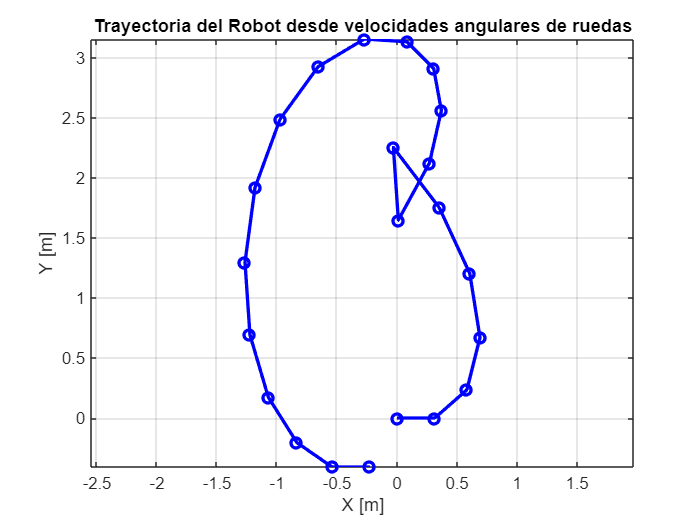


% Trazo
figure;
plot(poses(1,:), poses(2,:), 'b-o', 'LineWidth', 2);
xlabel('X [m]');
ylabel('Y [m]');
title('Trayectoria del Robot desde velocidades angulares de ruedas');
axis equal;
grid on;


% Tabla con todas las poses
pasos = (0:n)';  % Paso 0 es la pose inicial
x_vals = poses(1,:)';
y_vals = poses(2,:)';
theta_rad = poses(3,:)';
theta_deg = rad2deg(theta_rad);

% Crear tabla con la pose por paso
PoseTable = table(pasos, x_vals, y_vals, theta_rad, theta_deg, ...
    'VariableNames', {'Paso', 'X_m', 'Y_m', 'Theta_rad', 'Theta_deg'});

disp('Tabla de poses por paso:')

Tabla de poses por paso:


disp(PoseTable)

    Paso       X_m         Y_m        Theta_rad      Theta_deg 
    ____    _________    ________    ___________    ___________

      0             0           0              0              0
      1       0.31415           0        0.72025         41.267
      2       0.58196     0.23501         1.3252         75.931
      3       0.69095     0.66991          1.729         99.064
      4       0.60575       1.204          2.005         114.88
      5       0.35106      1.7532          2.223         127.37
      6     -0.030308      2.2526        -1.5027        -86.101
      7      0.010856      1.6486        -5.2118        -298.61
      8       0.26983      2.1233        -4.9358         -282.8
      9       0.36914      2.5605         -4.532        -259.66
     10       0.30521      2.9111         -3.927           -2

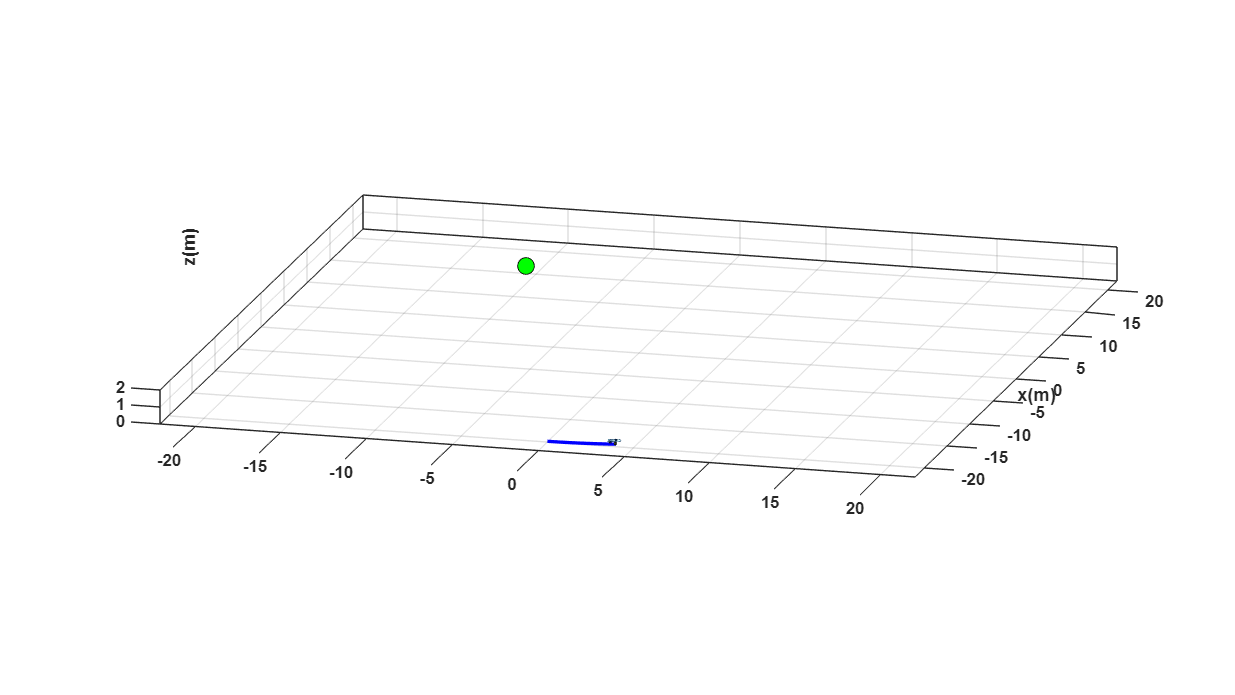










%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 200;              % Tiempo de simulación en segundos
ts = 0.1;              % Tiempo de muestreo en segundos
t = 0:ts:tf;           % Vector de tiempo
N = length(t);         % Número de muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1, N+1);    % Posición x del robot
y1 = zeros(1, N+1);    % Posición y del robot
phi = zeros(1, N+1);   % Orientación del robot en radianes

x1(1) = 0;             % Posición inicial x
y1(1) = -20;           % Posición inicial y
phi(1) = 0;            % Orientación inicial

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);    % Posición x del punto de control
hy = zeros(1, N+1);    % Posición y del punto de control
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = 1 * ones(1, N);       % Velocidad lineal de referencia
w = ones(1, N) / 20;      % Velocidad angular de referencia

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N
    phi(k+1) = phi(k) + w(k) * ts;  % Integración de orientación

    % Modelo cinemático diferencial
    xp1 = u(k) * cos(phi(k+1));
    yp1 = u(k) * sin(phi(k+1));

    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fig_3d_robot = figure;
set(fig_3d_robot,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(fig_3d_robot,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-22 22 -22 22 0 2]); % Ajustado a la trayectoria circular

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'b', 'lineWidth', 2);  % color azul
plot3(x1(end), y1(end), 0, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 10);  % Punto final

step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'b', 'lineWidth', 2);  % color azul
    pause(ts);
end

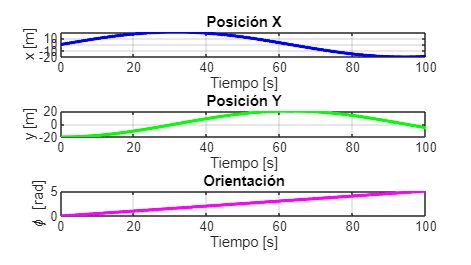


%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES ANGULARES DE LAS RUEDAS %%%%%%%%%%%%%%%%%%%

r = 0.1; % Radio de las ruedas (m)
L = 0.4; % Distancia entre ruedas (m)

wl = zeros(1, N); % Velocidad angular de rueda izquierda
wr = zeros(1, N); % Velocidad angular de rueda derecha

for k = 1:N
    wl(k) = (2 * u(k) - w(k) * L) / (2 * r);
    wr(k) = (2 * u(k) + w(k) * L) / (2 * r);
end



fig_pose_dinamica = figure;
set(fig_pose_dinamica, 'position', sizeScreen);

subplot(311)
plot(t, x1(1:N), 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('x [m]'), title('Posición X');

subplot(312)
plot(t, y1(1:N), 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('y [m]'), title('Posición Y');

subplot(313)
plot(t, phi(1:N), 'm', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('\phi [rad]'), title('Orientación');

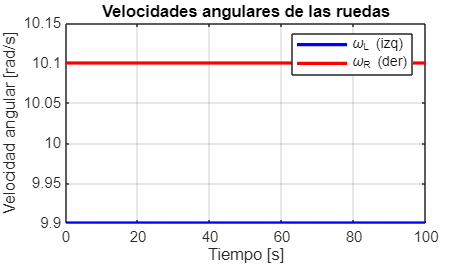


fig_vel_ruedas = figure;
set(fig_vel_ruedas, 'position', sizeScreen);
plot(t, wl, 'b', 'LineWidth', 2), hold on
plot(t, wr, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]')
ylabel('Velocidad angular [rad/s]')
legend('\omega_L (izq)', '\omega_R (der)')
title('Velocidades angulares de las ruedas')


%%%%%%%%%%%%%%%%%%% TABLA MUESTREADA CADA 5 SEGUNDOS %%%%%%%%%%%%%%%%%%%

muestreo_intervalo = 5;                              % Intervalo de muestreo en segundos
indices_muestreados = 1 : muestreo_intervalo/ts : N; % Cada 5 segundos
tiempos_muestreados = t(indices_muestreados)';       % Tiempo en segundos
wr_muestreados = wr(indices_muestreados)';           % ω_R muestreado
wl_muestreados = wl(indices_muestreados)';           % ω_L muestreado

tabla_vel_muestreadas = table(tiempos_muestreados, wr_muestreados, wl_muestreados, ...
    'VariableNames', {'Tiempo_s', 'omega_R_rad_s', 'omega_L_rad_s'});

disp('Tabla de velocidades angulares muestreadas cada 5 segundos:')

Tabla de velocidades angulares muestreadas cada 5 segundos:


disp(tabla_vel_muestreadas)

    Tiempo_s    omega_R_rad_s    omega_L_rad_s
    ________    _____________    _____________

        0           10.1              9.9     
        5           10.1              9.9     
       10           10.1              9.9     
       15           10.1              9.9     
       20           10.1              9.9     
       25           10.1              9.9     
       30           10.1              9.9     
       35           10.1              9.9     
       40           10.1              9.9     
       45           10.1              9.9     
       50           10.1              9.9     
       55           10.1              9.9     
       60           10.1              9.9     
       65           10.1              9.9     
       70           10.1              9.9     
       75           10.1              9.9     
       80           10.1              9.9     
    